## Sobel VHDL Code Generation

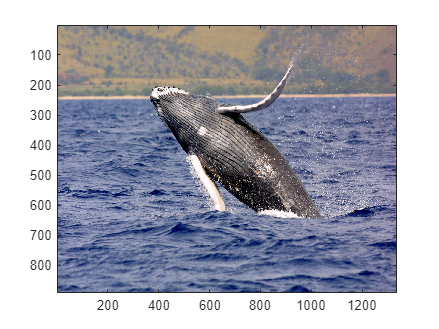

%type sobel
%codegen sobel

% Display Default Image
im = imread("humpback.jpg");
imagesc(im); % Default Image

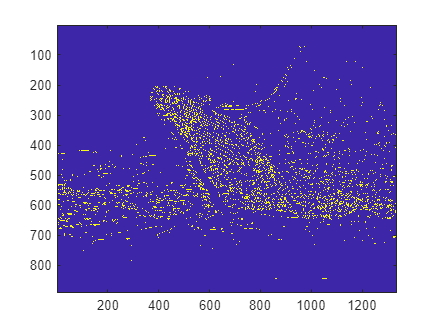


% Apply Sobel Filter
im2 = (0.2989 * double(im(:,:,1)) + 0.5870 * double(im(:,:,2)) + 0.1140 * double(im(:,:,3)))/255;
im_sobel = edge(im2, 'sobel');
imagesc(im_sobel)

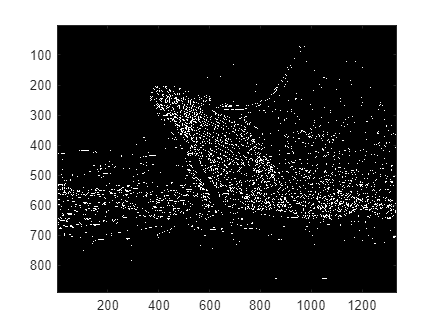


% Grayscale the Image
im_gray = repmat(im_sobel, [1 1 3]);
imagesc(im_gray);